## Data Input

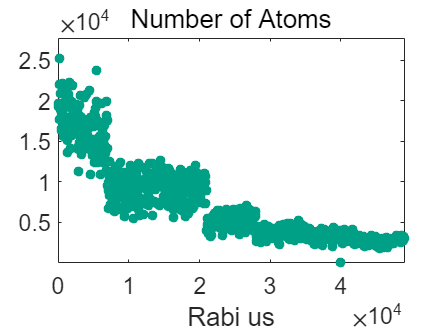

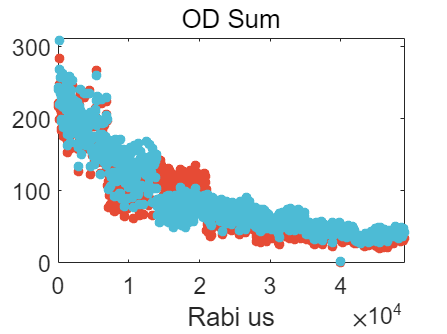

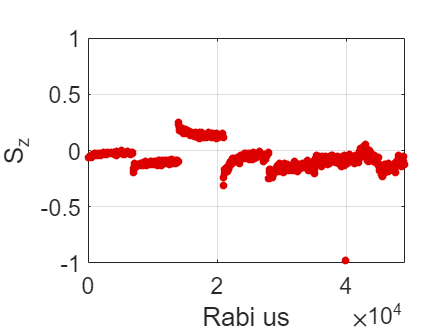

close all
clear all
maindir='D:\Data\Ramsey_Data\20230420-2\';
main_dir_0=maindir;
load([maindir,'\population.mat']);

## Precession Phase Uncertainty

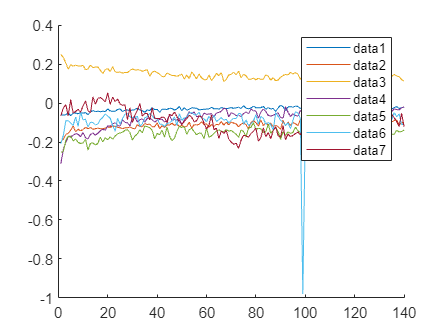

close all;

N = 100;   % 有效重复组数
x_label = 'Atom Number';
y_label = 'Phase Std';
f_title = 'B Field Shift (2)';
ShotNoise = @(x) 1./sqrt(x);

%%   Reshape   %%
precession=[1 10 20 40 60 80 100];
repeat_se = length(relativeOD)/length(precession);
reshape_phase=reshape(relativeOD,repeat_se,length(precession));

n_atom = numberofatoms1+numberofatoms2;
reshape_n = reshape(n_atom,repeat_se,length(precession));
reshape_n(1:40,:) = [];



for i = 1:length(precession)
    atom_num(i) = mean(reshape_n(:,i));
    num_std(i) = std(reshape_n(:,i));
    %shot_noise(i) = 1/sqrt(atom_num(i));
end


%%   Precession Phase   %%
f1 = figure;
hold on;
for i=1:length(precession)
    plot(1:repeat_se,reshape_phase(:,i));
end
legend;

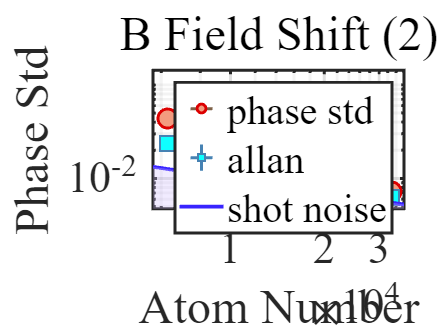


%%   Drift Removal   %%
reshape_phase(1:40,:) = [];
reshape_phase(59,:)=[];
phase_mean=mean(reshape_phase);
phase_std=std(reshape_phase);
phase_weight=1./phase_std.^2;


f2=figure;

%%   Std   %%
e1 = errorbar(atom_num,phase_std,num_std/sqrt(N-1),'o','horizontal');
e1.CapSize=0;
e1.MarkerSize=13;
e1.LineWidth=2;
e1.Color=colors(9,:);
e1.MarkerEdgeColor=colors(8,:);
e1.MarkerFaceColor=colors(5,:);

hold on;

%%   Differential Std   %%
% e2 = errorbar(atom_num,DiffStd(reshape_phase),num_std/sqrt(N-1),'square','horizontal');
% set(e2,'Color',[0.22 0.14 1],'MarkerFaceColor',[0 0.99 0.604],...
%     'CapSize',0,'LineWidth',2,'MarkerSize',13);

%%   Axis Settings   %%
xlabel(x_label);
ylabel(y_label);
title(f_title);
x_max = max(atom_num)*1.1;
x_min = min(atom_num)*0.9;
y_max = max(phase_std)+0.1;
y_min = ShotNoise(x_max)*0.9;
xlim([x_min x_max]);
ylim([y_min y_max]);

set(gca,'XScale','log','YScale','log');
set(gca,'FontSize',30,'FontName','times new roman','linewidth',2);

%%   Allan Std   %%
[allan,allan_std] = AllanStd(reshape_phase);
e3 = errorbar(atom_num,allan,allan_std,allan_std,...
    num_std/sqrt(N-1),num_std/sqrt(N-1),'square');
set(e3,'Color',[0.274 0.51 0.7],'MarkerFaceColor',[0.059 1 1],...
    'CapSize',0,'LineWidth',2,'MarkerSize',13);

%%   Shot Noise   %%
l1 = fplot(ShotNoise,[1,x_max]);
set(l1,'color',[0.22 0.14 1],'LineWidth',2.5);
x_temp = x_min+5:x_max-15;
area(x_temp,ShotNoise(x_temp),'ShowBaseLine','off','BaseValue',0.001,'FaceAlpha',0.3,...
    'FaceColor',[0.82 0.74 1],'EdgeAlpha',0,'EdgeColor','none','LineWidth',2);


legend('phase std','allan','shot noise');
grid on;
set(gca,'MinorGridAlpha',0.05,'MinorGridLineStyle','-');

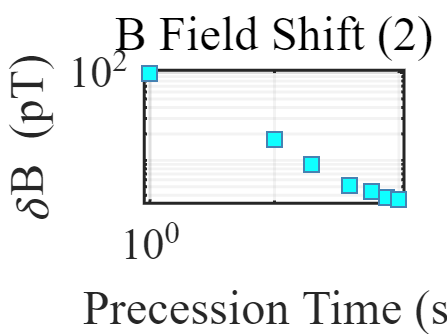


%savefig(f2,[main_dir_0,'\RamseyStd.fig'],'compact');


%%   Magnetic Noise   %%
x_label = 'Precession Time (s)';
y_label = '\deltaB (pT)';
%f_title = 'B Field Shift (6)';
f3 = figure;

gamma = 2*pi*2.07e6*5;
delta_B = allan./precession/gamma;
delta_B_std = allan_std./precession/gamma;

e4 = errorbar(precession,delta_B.*1e12,delta_B_std.*1e12,'square');
set(e4,'Color',[0.274 0.51 0.7],'MarkerFaceColor',[0.059 1 1],...
    'CapSize',0,'LineWidth',2,'MarkerSize',13);

xlabel(x_label);
ylabel(y_label);
title(f_title);

xlim([min(precession)*0.9 max(precession)*1.1]);
ylim([min(delta_B)*0.9e12 max(delta_B)*1.1e12]);
set(gca,'XScale','log','YScale','log');
set(gca,'FontSize',30,'FontName','times new roman','linewidth',2);
grid on;
set(gca,'MinorGridAlpha',0.05,'MinorGridLineStyle','-');


%savefig(f2,[main_dir_0,'\deltaB.fig'],'compact');
save([main_dir_0,'\process.mat']);


## Pulse Induced Phase Uncertainty

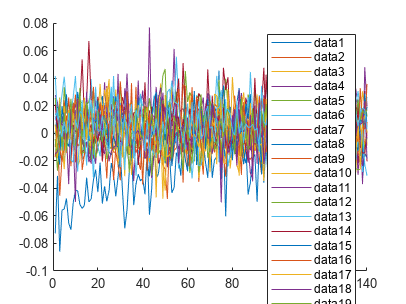

close all;

N = 100;   % 有效重复组数
x_label = 'Probe Pulse us';
y_label = 'Phase Std';
ShotNoise = @(x) 1./sqrt(x);

%%   Reshape   %%
pulse = 10:20:390;
repeat_se = length(relativeOD)/length(pulse);
reshape_phase=reshape(relativeOD,repeat_se,length(pulse));

n_atom = numberofatoms1+numberofatoms2;
reshape_n = reshape(n_atom,repeat_se,length(pulse));
reshape_n(1:40,:) = [];
for i = 1:length(pulse)
    atom_num(i) = mean(reshape_n(:,i));
    num_std(i) = std(reshape_n(:,i));
    %shot_noise(i) = 1/sqrt(atom_num(i));
end
shot_noise=1/sqrt(mean(n_atom(41:140)));

%%   Precession Phase   %%
f1 = figure;
hold on;
for i=1:length(pulse)
    plot(1:repeat_se,reshape_phase(:,i));
end
legend;

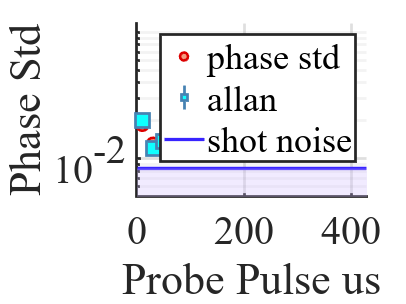


%%   Drift Removal   %%
reshape_phase(1:40,:) = [];
phase_mean=mean(reshape_phase);
phase_std=std(reshape_phase);
phase_weight=1./phase_std.^2;


f2=figure;

%%   Std   %%
e1 = scatter(pulse,phase_std,'o','SizeData',90);
e1.LineWidth=2;
e1.MarkerEdgeColor=colors(8,:);
e1.MarkerFaceColor=colors(5,:);

hold on;

%%   Differential Std   %%
% e2 = errorbar(atom_num,DiffStd(reshape_phase),num_std/sqrt(N-1),'square','horizontal');
% set(e2,'Color',[0.22 0.14 1],'MarkerFaceColor',[0 0.99 0.604],...
%     'CapSize',0,'LineWidth',2,'MarkerSize',13);

%%   Axis Settings   %%
xlabel(x_label);
ylabel(y_label);
x_max = max(pulse)*1.1;
x_min = 0;
y_max = max(phase_std)+0.1;
y_min = min(phase_std)-0.1;
xlim([x_min x_max]);
ylim([5e-3 y_max]);

set(gca,'XScale','linear','YScale','log');
set(gca,'FontSize',30,'FontName','times new roman','linewidth',2);

%%   Allan Std   %%
[allan,allan_std] = AllanStd(reshape_phase);
e3 = errorbar(pulse,allan,allan_std,'square');
set(e3,'Color',[0.274 0.51 0.7],'MarkerFaceColor',[0.059 1 1],...
    'CapSize',0,'LineWidth',2,'MarkerSize',13);

%%   Shot Noise   %%
x_temp = x_min+1:x_max-1;
l1 = plot(x_temp,shot_noise.*ones(length(x_temp)),'LineWidth',2.5,...
    'Color',[0.22 0.14 1]);
area([x_min,x_max],[shot_noise,shot_noise],'ShowBaseLine','off',...
    'BaseValue',0.001,'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],...
    'EdgeAlpha',0,'EdgeColor','none','LineWidth',2);

grid on;
set(gca,'MinorGridAlpha',0.05,'MinorGridLineStyle','-');
legend('phase std','allan','shot noise');


savefig(f2,[main_dir_0,'\PulseStd.fig']);


function [d_std] = DiffStd(re_phase)
for i=1:length(re_phase(1,:))
    phase2 = re_phase(:,i);
    phase2(1) = [];
    phase1 = re_phase(:,i);
    phase1(end) = [];

    d_phase = phase2-phase1;
    d_std(i) = std(d_phase)./sqrt(2);
end
end

function [allan,allan_std] = AllanStd(re_phase)
for i=1:length(re_phase(1,:))
    phase2 = re_phase(:,i);
    phase2(1) = [];
    phase1 = re_phase(:,i);
    phase1(end) = [];

    d_phase = ((phase2-phase1)./sqrt(2)).^2;
    allan(i) = sqrt(mean(d_phase));
    allan_std(i) = std(d_phase)./sqrt(length(re_phase(:,1))-2);
    allan_std(i) = allan_std(i)./(2*allan(i));
end
end